% Presetting
PosExtract=[0; 0; 0; 1];

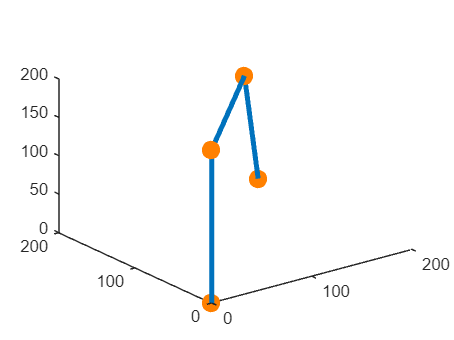

% 3-DoF Manipulator Type 2 Inverse Kinematics test by plot graph
EndpointPos = [200;200;0];

% Inverse Kinematics Solving
x = EndpointPos(1);
y = EndpointPos(2);
z = EndpointPos(3);
L1=200;
L2=200;
L3=200;
xn = sqrt(x^2 + y^2);
yn = z - L1;
theta1 = atan2(y, x);
theta3 = -acos((xn^2+yn^2-L2^2-L3^2)/(2*L2*L3));
theta2 = atan2(yn, xn) - atan2(L3*sin(theta3), L2+L3*cos(theta3));

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = L1;
T01 = DHParameter(a0, alpha0, d1, theta1);

% Arm1 to Arm2
a1 = 0;
alpha1 = pi/2;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3);

% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
theta4 = 0;
T3E = DHParameter(a3, alpha3, d4, theta4);

% Base to Each Coordinate
T02 = T01*T12;
T03 = T01*T12*T23;
T0E = T01*T12*T23*T3E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p03=T03*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot3([PosExtract(1,1), p02(1,1), p03(1,1), p0E(1,1)], [PosExtract(2,1), p02(2,1), p03(2,1), p0E(2,1)], [PosExtract(3,1), p02(3,1), p03(3,1), p0E(3,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0];